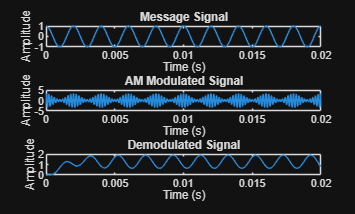

clc;
clear;
close all;

%% PARAMETERS
fs = 100000;            % Sampling frequency
t = 0:1/fs:0.02;        % Time vector

fm = 500;               % Message frequency (Hz)
fc = 5000;              % Carrier frequency (Hz)

Am = 1;                 % Message amplitude
Ac = 2;                 % Carrier amplitude

mu = 0.7;               % Modulation index

%% MESSAGE SIGNAL
m = Am*cos(2*pi*fm*t);

%% CARRIER SIGNAL
c = Ac*cos(2*pi*fc*t);

%% AM MODULATION (TRANSMITTER)
s = Ac*(1 + mu*m).*cos(2*pi*fc*t);

%% RECEIVER - ENVELOPE DETECTOR
rectified = abs(s);     % Rectification

% Low pass filter design
[b,a] = butter(5,fm*2/fs);

demod = filter(b,a,rectified);

%% FREQUENCY ANALYSIS
N = length(t);
f = (-N/2:N/2-1)*(fs/N);

M = fftshift(abs(fft(m)));
S = fftshift(abs(fft(s)));
D = fftshift(abs(fft(demod)));

%% PLOTTING

figure;

subplot(3,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(3,1,2)
plot(t,s)
title('AM Modulated Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(3,1,3)
plot(t,demod)
title('Demodulated Signal')
xlabel('Time (s)')
ylabel('Amplitude')

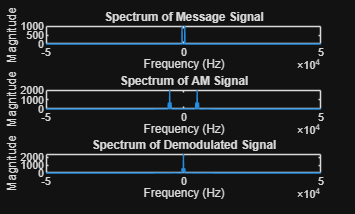


figure;

subplot(3,1,1)
plot(f,M)
title('Spectrum of Message Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,1,2)
plot(f,S)
title('Spectrum of AM Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,1,3)
plot(f,D)
title('Spectrum of Demodulated Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')